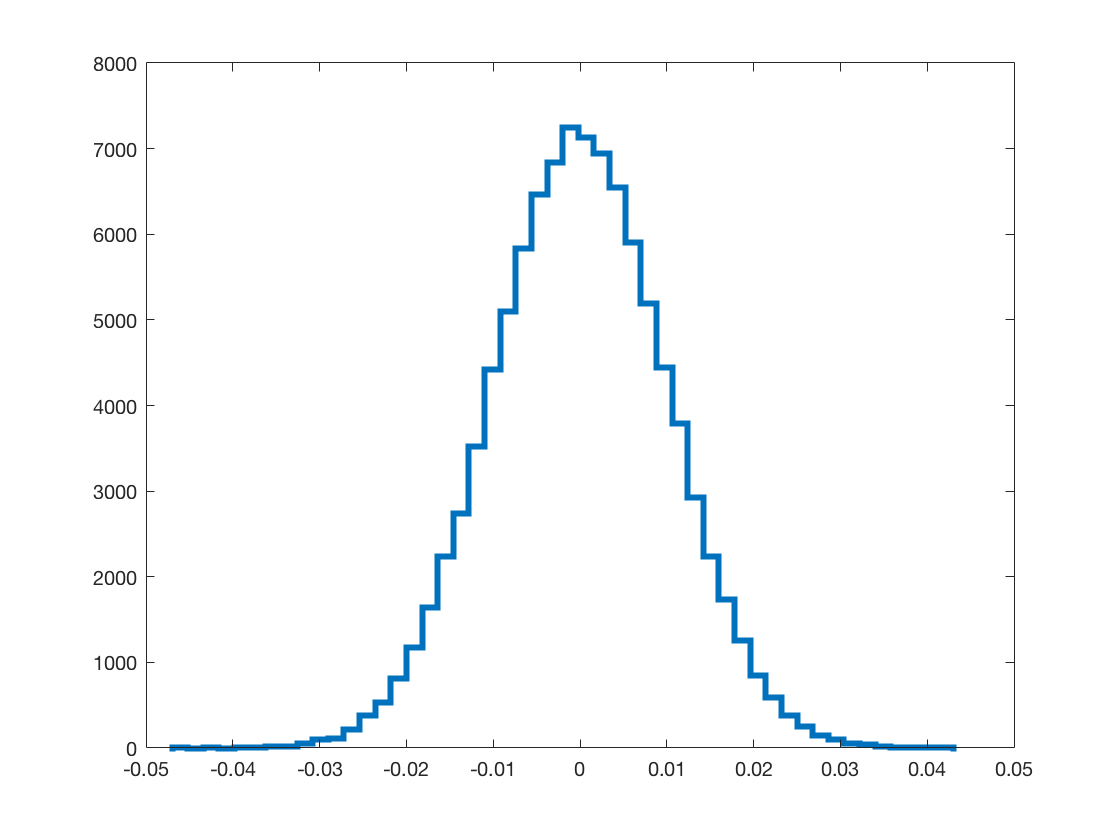

% 1: 

d1 = random('Normal', 0., 0.01, [1,100000]);
histogram(d1,50,'DisplayStyle',"stairs",'LineWidth',3)
xlim([-0.05,0.05])

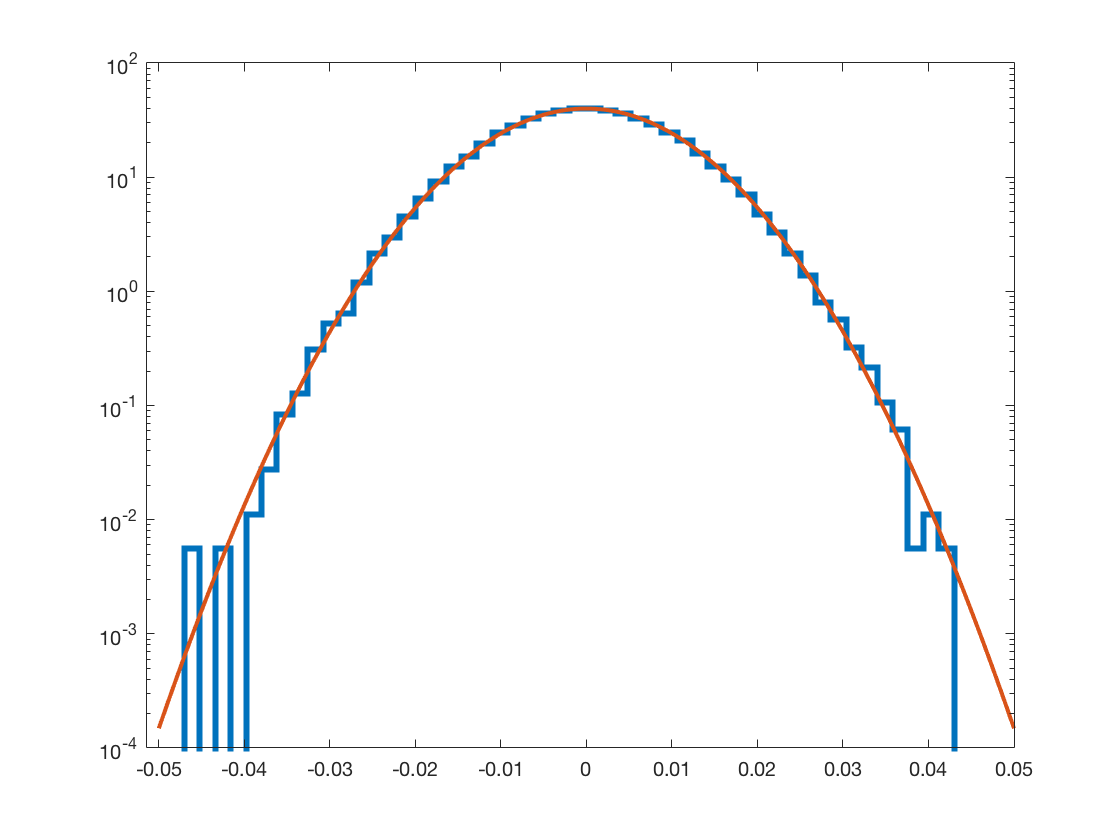


histogram(d1,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
x1 = linspace(-0.05,0.05,1000);
pd = makedist("Normal","mu",0.,"sigma",0.01);
plot(x1,pdf(pd,x1),"LineWidth",2);
set(gca,'YScale','log')
hold off

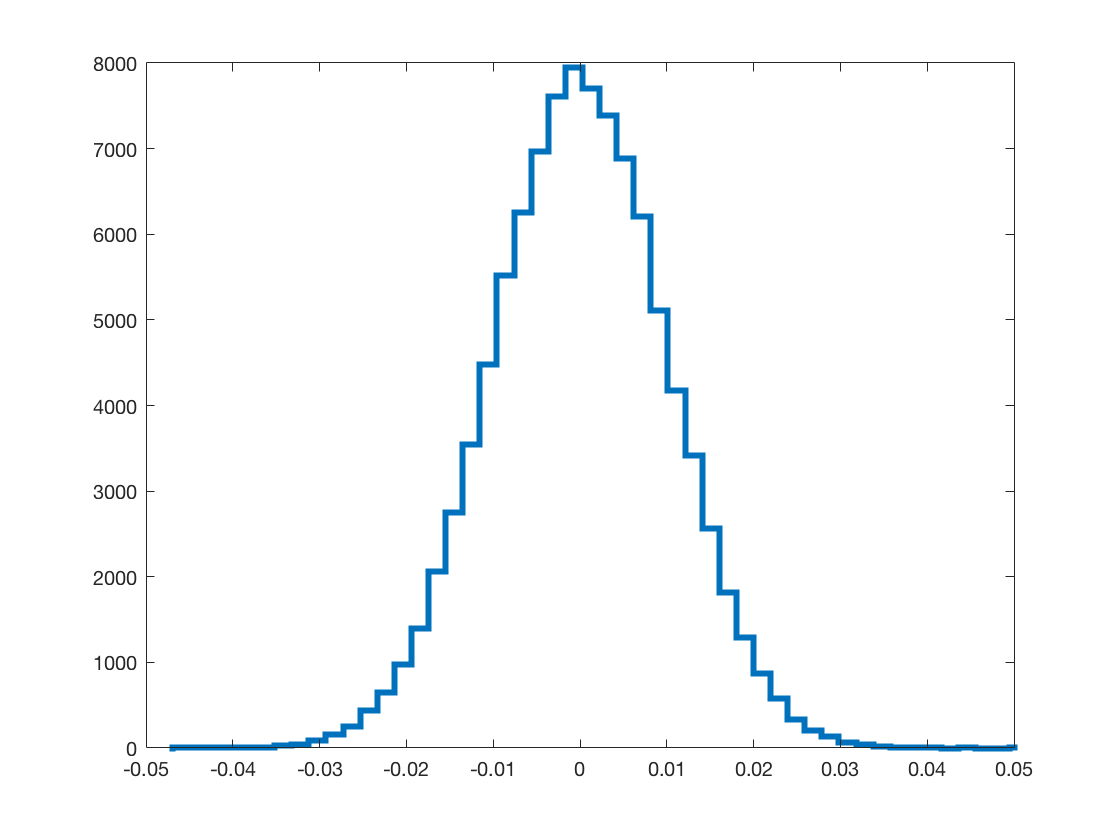



% 2: Exponential distribution
d2 = random('Normal', 0., 0.01, [1,100000]);
histogram(d2,50,'DisplayStyle',"stairs",'LineWidth',3)
xlim([-0.05,0.05])

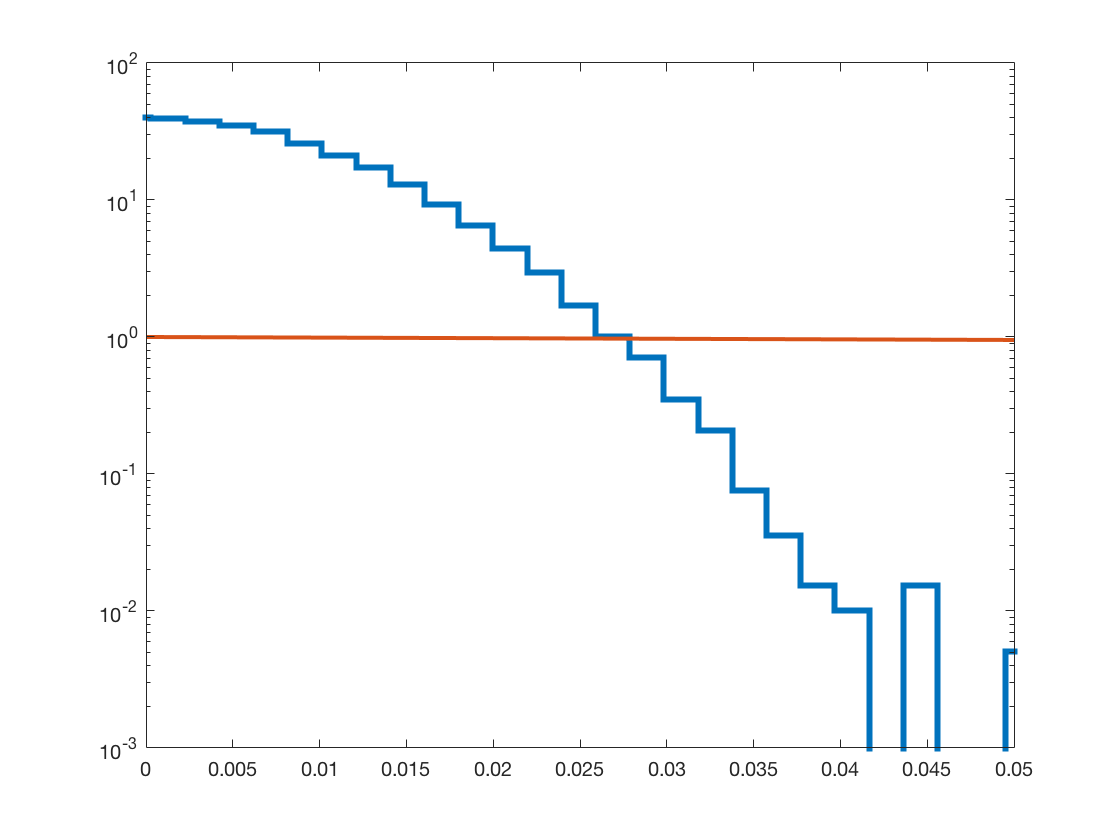


histogram(d2,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
xlim([0,0.05])
hold on
x2 = linspace(-0.05,0.05,1000);
expD = makedist('Exponential','mu',1);
plot(x2,pdf(expD,x2),"LineWidth",2);
set(gca,'YScale','log')
hold off